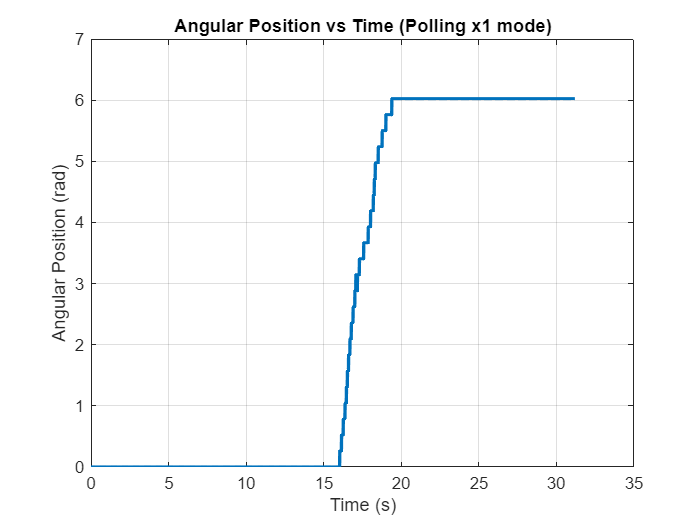

data = Polling_x1;
data_ar = cell(1, length(data.Data)); % Initialize cell array
for i = 1:length(data.Data)
    data_ar{i} = data.Data(i); % Store each element
end

% Convert cell array to numeric array
data_ar_num = cell2mat(data_ar);

% Plot
time = data.Time; % assuming time is already numeric
plot(time, data_ar_num, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Angular Position (rad)');
title('Angular Position vs Time (Polling x1 mode)');
grid on;